# LoopBack over MATLAB

#### By El Mehdi BENSEDDIK

## I- Record Audio

Recording data from an audio input device (such as a microphone connected to your system) for processing in MATLAB.

The following examples show how to use the record methods.

#### Record Microphone Input

This exapmle shows how to record microphone input, play back the recording, and store the recorded audio signal in a numeric array. You must first connect a microphone to your system.

Create an *audiorecorder* object named recObj for recording audio input.

recObj = audiorecorder(48000,16,1)       % display its properties

recObj =   audiorecorder with properties:

          SampleRate: 48000
       BitsPerSample: 16
    NumberOfChannels: 1
            DeviceID: -1
       CurrentSample: 1
        TotalSamples: 0
             Running: 'off'
            StartFcn: []
             StopFcn: []
            TimerFcn: []
         TimerPeriod: 0.0500
                 Tag: ''
            UserData: []
                Type: 'audiorecorder'


As you see *audiorecorder* creates an 8 KHz, 8-bit, 1-channel *audiorecorder* object.

We can change all these parameters like we want for example we can replace the  8 KHz with 44.1 KHz in the SampleRate also NumberOfChannels regarding how many channels do we have in our sound card, etc.

Record voice for 6 seconds or can choose your own time recording.

disp('Start recording... Say somthing...!!')

Start recording... Say somthing...!!


recordblocking(recObj,6);
disp('End of recording.')

End of recording.


Play back the recording.

disp('Record is playing... we can hear what we said previously')

Record is playing... we can hear what we said previously


% play(recObj);

Store data in double-precision array.

recordData = getaudiodata(recObj);

Plot the audio samples.

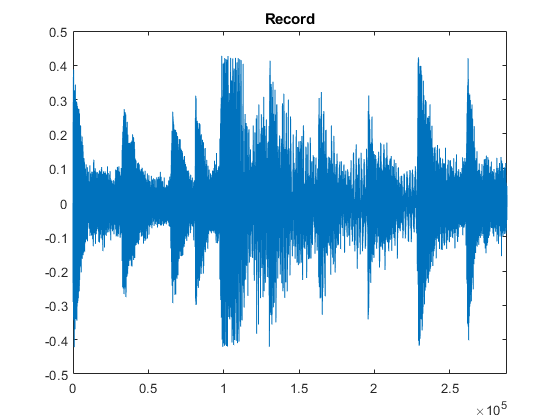

plot(recordData)
title('Record')
xlim([0 length(recordData)])

## II- Write Audio

#### Description : 

`audiowrite(`*filename,recordData,SampleRate*`)` writes a matrix of audio data, recordData, with sample rate `Fs` to a file called `filename`. The `filename` input also specifies the output file format. The *output data type* depends on the output file format and the data type of the audio data, recordData. 

audiowrite('myrecord.wav',recordData,recObj.SampleRate)

#### Specify the Quality of the Recording

By default, an *audiorecorder* object uses a sample rate of 8 KHz, a depth of 8-bit (8 bits per sample), and a single audio channel. These settings minimize the required amount of data storage. For higher quality recordings, increase the sample rate or bit depth.

For example, typical compact disks use a sample rate or 44.1 KHz and a 16-bit depth. Create an *audiorecorder* object to record in stereo mode (two channels) with those settings : 

% myRecObj = audiorecorder(44100,16,2)

#### Note : 

Most sound cards support sample rates between approximately 5 and 48 KHz. Specifying sample rates outside this range can produce unexpected results.

#### Tips :

- To use an *audiorecorder* object, your system must have a properly installed and configured sound card.

- *audiorecorder *is not intended for long, high-sample-rate recording. *audiorecorder *uses system memory for storage and does not use disk buffering. When you attempt a large recording, your MATLAB performance somtimes degrades over time. 

#### References :

- [https://www.mathworks.com/help/matlab/import_export/record-and-play-audio.html](https://www.mathworks.com/help/matlab/import_export/record-and-play-audio.html)